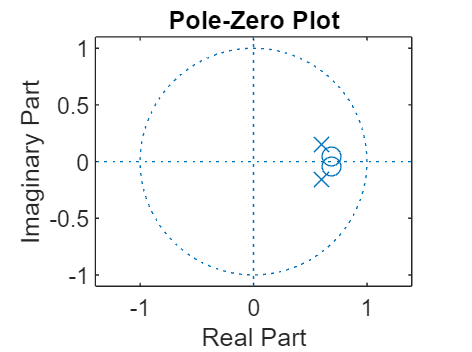

fs=1000;N=600;M=600;
fz1=80; z1=0.68*exp(-1j*2*pi*fz1/fs); z2=z1'; z=[z1,z2]';
fp1=300; p1=0.6*exp(-1j*2*pi*fp1/fs); p2=p1'; p=[p1,p2]';
figure;zplane(z,p)

[b,a]=zp2tf(z,p,1);
[R,p,C]=residuez(b,a);
hn(1:M)=R(1)*(p(1).^(0:M-1))+R(2)*(p(2).^(0:M-1));
hn(1)=hn(1)+C(1);